# Scitran project reporting

Illustrates searching the Flywheel database from Matlab for subject information within a particular project.  

## Authorization

Open the scitran object, here we name the instance 'vistalab'. This uses the URL of your Flywheel instance and the API key. 

st = scitran('stanfordlabs');

## Search for all projects 

projects = st.search('projects', 'summary', true);

Found 49 (project)


## Get the number of sessions in each project

projectLabels = stPrint(projects, 'project','label'); 


 project label
-----------------------------
	1 - SVIP Released Data (SIEMENS) 
	2 - Autism Phenome 
	3 - ENGAGE 
	4 - Weston Havens 
	5 - SVIP: Unreleased Data 
	6 - UMN 
	7 - HCP_preproc 
	8 - VWFA FOV 
	9 - Reading Longitude: DWI 
	10 - SVIP (Philips) 
	11 - PRATIK 
	12 - BCBL_ILLITERATES 
	13 - CoRR 
	14 - ADNI: T1 
	15 - DES-fMRI 
	16 - ALDIT 
	17 - Graphics assets 
	18 - ADNI: DWI (MCI) 
	19 - ADNI: DWI (AD) 
	20 - HCP 
	21 - showdes 
	22 - VWFA FOV Hebrew 
	23 - ADNI: DWI (Normal Controls) 
	24 - fastrest 
	25 - Templates Adult 
	26 - VWFA 
	27 - Rorie PLoS One 2010 
	28 - Brain Beats 
	29 - Dental 
	30 - SOC ECoG (Hermes) 
	31 - retinotopy 
	32 - Peds: Reading - Feldman 
	33 - MS: JWDay 
	34 - ds001 
	35 - Albinism: Control 
	36 - Oral Eye 
	37 - Renderings 
	38 - TBI: NeuroCor 
	39 - Templates Neonatal 
	40 - DEMO 
	41 - Templates Pediatric 
	42 - Templates Macaque 
	43 - Velscope 
	44 - Kiani Current Biology 2014 
	45 - EJ Apricot 
	46 - Recon Test 
	47 - ENGAGE-AFQ 
	48 - P

numSessions   = stProjectGet(st, projects, 'numsessions');

## Plot distribution of number of sessions

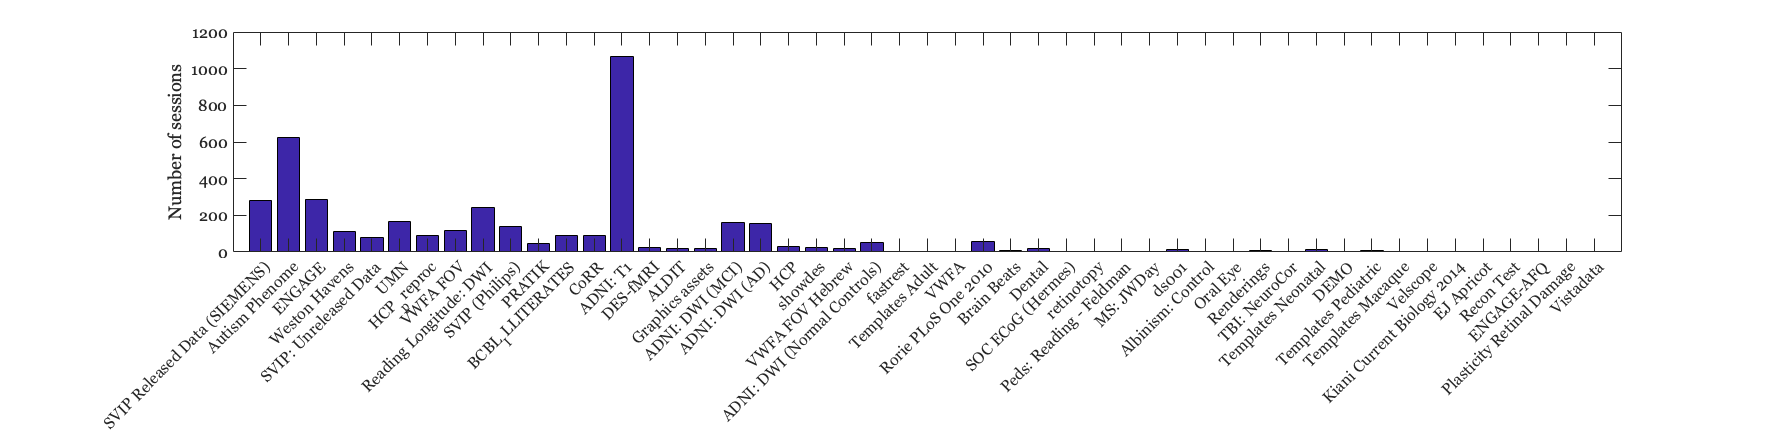

mrvNewGraphWin([],'wide');
bar(numSessions);
set(gca,'XTick', 1:numel(projects), 'XTickLabels', projectLabels);
xtickangle(45);
ylabel('Number of sessions');

set(gca,'yscale','log')



## 4. Search for sessions within a given project

    Find the sessions in the project, which contain the subject information

% project = 'SVIP Released Data (SIEMENS)';
project = 'VWFA FOV';
h = st.projectHierarchy(project);

sessions = st.search('sessions','project label exact', project);
subjects = st.search('subject','project label exact', project);

fprintf('Found %d sessions in the %s project.', length(sessions), project);

Found 116 sessions in the VWFA FOV project.

## 5. Parse the subject information

subjects = stSubjectInfo(sessions);
codes    = stSubjectGet(subjects,'code');
disp(codes);

    'mv'
    'vm'
    'mw'
    'ex11352'
    'ol'
    'gt'
    'ws'
    'dl'
    'ex9610'
    'jg'
    'ex8695'
    'ex8794'
    'ex9715'
    'sl'
    'jv'
    'ex8822'
    'ex8715'
    'ex8724'
    'ex8788'
    'ex9577'
    'ak'
    'ex9638'
    'ex10006'
    'tl'
    'ex9518'
    'ex9644'
    'ex9647'
    'ex9667'
    'ex10766'
    'ex13414'
    'ex8823'
    'ex9641'
    'ex10673'
    'ex10683'
    'ex10831'
    'ex11030'
    'ex9669'
    'wandell.vwfa'
    'ex10665'
    'ex9691'
    'ex10147'
    'ex9579'
    'ex9626'
    'ex10039'
    'ex10040'
    'ex8596'
    'ex7739'
    'ex9462'
    'ex9578'
    'ex8716'
    'ex9555'
    'ex9728'
    'ex10765'
    'ex8789'
    'ex8795'
    'ex11347'
    'ex13413'
    'ex13428'
    'ex9668'
    'ex8696'
    'ex8727'
    'ex8750'
    'ex9461'
    'ex8613'
    'ex9554'
    'ex13642'
    'ex8605'
    'ex10830'
    'ex10606'
    'ex6994'
    'ex4110'
    'ex6785'
    'ex8403'
    'ex8725'
    'ex8553'
    'ex10573'
    'ex7030'
    'ras'
    'ex8406

## 6. Plot Sex Distribution

sex      = stSubjectGet(subjects,'sex');
nMale    = sum(sex=='m');
nFemale  = sum(sex =='f');
nUnknown = sum(sex == 'u');
labels = {['Male = ',    num2str(nMale)],...
          ['Female = ',  num2str(nFemale)],...
          ['Unknown = ', num2str(nUnknown)]};
pie([nMale, nFemale, nUnknown], labels);

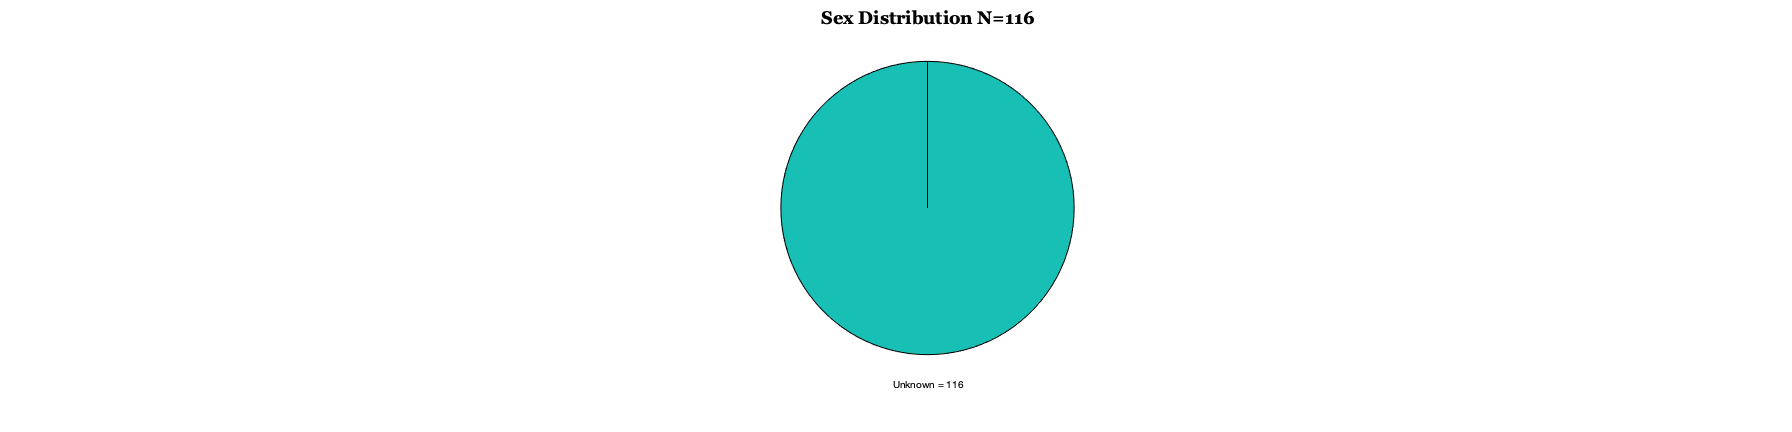

title(['Sex Distribution N=', num2str(length(subjects))]);

## 7. Plot Age Distribution

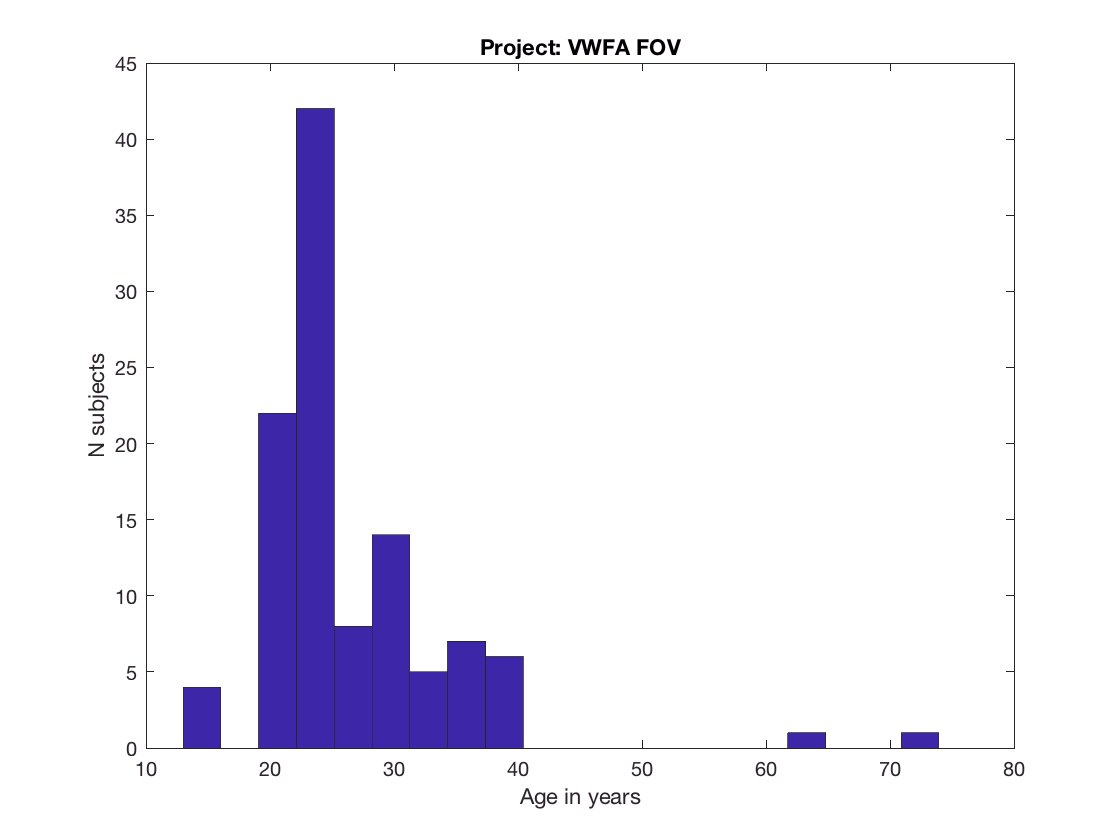

ages = stSubjectGet(subjects,'age');
figure; hist(ages,20); 
xlabel('Age in years'); ylabel('N subjects');
title(sprintf('Project: %s',project));